# Script to analyze PSC event data from pclamp

REMEMBER TO PULL AT THE BEGINNING OF EVERY SESSION AND PUSH AT THE END IF CODE CHANGES!!!!

## Analyze Synaptic currents

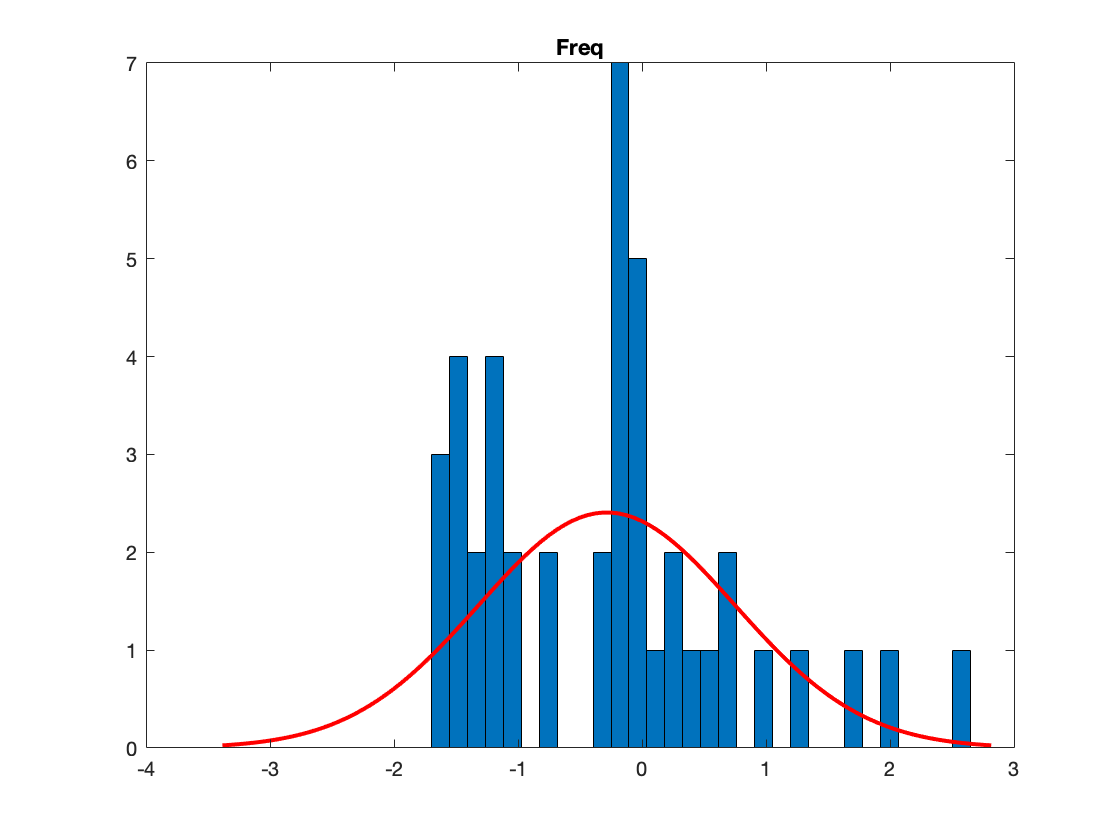

Error using FindDuplicates (line 5)
Unrecognized table variable name 'EventStart_ms_'.

Error in AnalyzePSC (line 91)
    [RefinedData] = FindDuplicates(EventData{i},1);

clear
%% NMDA/AMPA
% Path to folders to be analyzed
[Path] = uigetdir;
% Path to folder where results are to be saved
[SavePath] = uigetdir;
% Folders = dir(Path);
% AnalyzePSC(Path to folders, nbins for CDFs)
Data = AnalyzePSC(Path,50,30);

## Export data files 

ExportFiles(Data,SavePath)

